clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='Naca2012';    %%Profilname gerade nur NACA 4-digit profile
alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=12;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof(1)=profile_transform(R,r,name,lamda_A,z, alpha_A, t);
   else
       if check_existing(prof,r) == 0
            l=length(prof);
            prof(l+1)=profile_transform(R,r,name,lamda_A,z, alpha_A, t);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits. Anderen Profilposition waehlen!')
       end
   end
end

radii =      3    10    12    13    15    17


existing = logical
   1


Profil bei an dieser Stelle existiert bereits. Anderen Profilposition waehlen!


## plot

l = 6

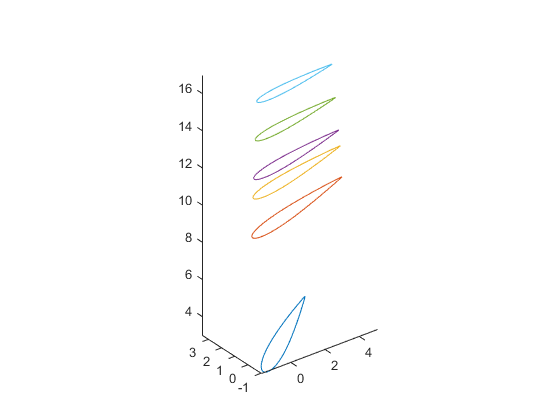

bld_plot(prof)